# Comparing FIR Differentiators

This live script is based on the discussion in MATLAB Exercise 8.15 of 

*Discrete-Time Signals and Systems: A MATLAB Integrated Approach*

by O. Alkin, CRC Press, 2025.

A FIR differentiator is to be designed to filter an analog signal sampled with a sampling rate of $f_{s}=200$ Hz. In the first step, we will compute the spectrum of an ideal differentiator that will be useful for graphing later.

Omega = [-1:0.01:1]*pi;  % Vector of angular frequencies
fs = 200;                % Sampling rate
Hd = j*Omega*fs;         % Ideal differentiator spectrum

Design a length-$9$ type-III differentiator using a rectangular window. Graph its magnitude response along with the magnitude response of the ideal differentiator.

h1 = ss_fir1(9,0,'diff','rect')*fs

h1 =   -50.0000
   66.6667
 -100.0000
  200.0000
         0
 -200.0000
  100.0000
  -66.6667
   50.0000


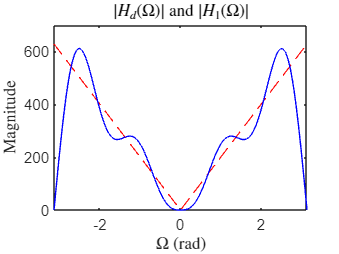

H1 = freqz(h1,1,Omega);
plot(Omega,abs(Hd),'r--',Omega,abs(H1),'b');
axis([-pi,pi,0,700]);
set(0,'defaultTextInterpreter','latex');
title('$|H_{d}(\Omega)|$ and $|H_{1}(\Omega)|$');
xlabel('$\Omega$ (rad)');
ylabel('Magnitude');

Design a length-$9$ type-III differentiator using a Hamming window. Graph its magnitude response along with the magnitude response of the ideal differentiator.

% Type_III with Hamming window
h2 = ss_fir1(9,0,'diff','hamming')*fs

h2 =    -4.0000
   14.3154
  -54.0000
  173.0538
         0
 -173.0538
   54.0000
  -14.3154
    4.0000


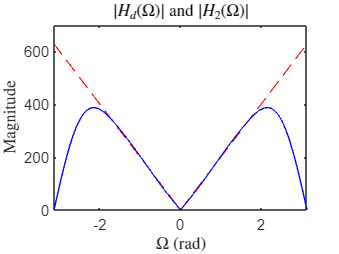

H2 = freqz(h2,1,Omega);
plot(Omega,abs(Hd),'r--',Omega,abs(H2),'b');
axis([-pi,pi,0,700]);
title('$|H_{d}(\Omega)|$ and $|H_{2}(\Omega)|$');
xlabel('$\Omega$ (rad)');
ylabel('Magnitude');

Design a length-$9$ type-IV differentiator using a rectangular window. Graph its magnitude response along with the magnitude response of the ideal differentiator.

h3 = ss_fir1(8,0,'diff','rect')*fs

h3 =    -5.1969
   10.1859
  -28.2942
  254.6479
 -254.6479
   28.2942
  -10.1859
    5.1969


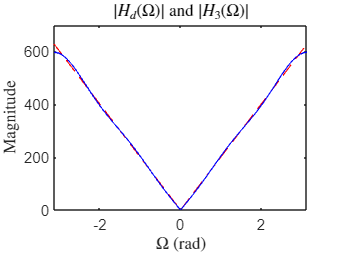

H3 = freqz(h3,1,Omega);
plot(Omega,abs(Hd),'r--',Omega,abs(H3),'b');
axis([-pi,pi,0,700]);
title('$|H_{d}(\Omega)|$ and $|H_{3}(\Omega)|$');
xlabel('$\Omega$ (rad)');
ylabel('Magnitude');

Design a length-$9$ type-IV differentiator using a Hamming window. Graph its magnitude response along with the magnitude response of the ideal differentiator.

h4 = ss_fir1(8,0,'diff','hamming')*fs

h4 =    -0.4158
    2.5790
  -18.1751
  243.0476
 -243.0476
   18.1751
   -2.5790
    0.4158


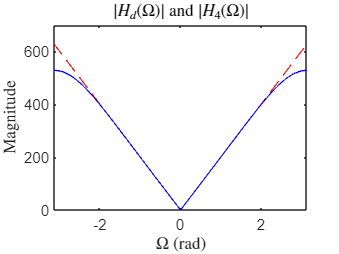

H4 = freqz(h4,1,Omega);
plot(Omega,abs(Hd),'r--',Omega,abs(H4),'b');
axis([-pi,pi,0,700]);
title('$|H_{d}(\Omega)|$ and $|H_{4}(\Omega)|$');
xlabel('$\Omega$ (rad)');
ylabel('Magnitude');

h5 = [1,-1]*200;  % First backward difference

Generate a sawtooth signal and process through each of the five differentiators. Graph the output signal for each.

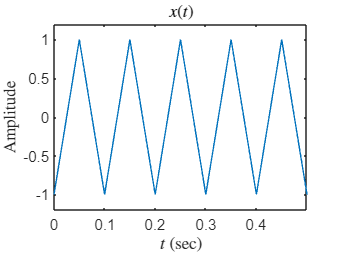

t = [0:1/fs:0.5];
x = sawtooth(2*pi*10*t,1/2);
plot(t,x);
axis([0,0.5,-1.2,1.2]);
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$x(t)$');

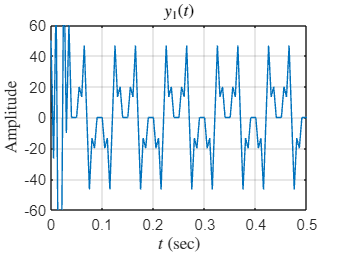

%-------------------------------------------------
y1 = conv(x,h1);
plot(t,y1([1:101])); grid;
axis([0,0.5,-60,60]);
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$y_{1}(t)$')

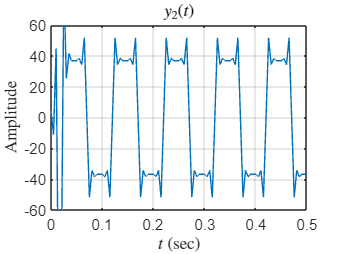

%-------------------------------------------------
y2 = conv(x,h2);
plot(t,y2([1:101])); grid;
axis([0,0.5,-60,60]);
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$y_{2}(t)$');

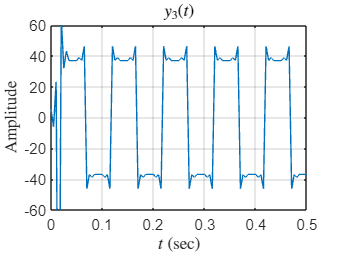

%-------------------------------------------------
y3 = conv(x,h3);
plot(t,y3([1:101])); grid;
axis([0,0.5,-60,60]);
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$y_{3}(t)$');

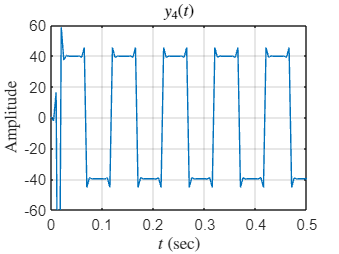

%-------------------------------------------------
y4 = conv(x,h4);
plot(t,y4([1:101])); grid;
axis([0,0.5,-60,60]);
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$y_{4}(t)$');

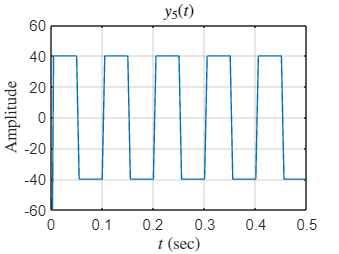

%-------------------------------------------------
y5 = conv(x,h5);
plot(t,y5([1:101])); grid;
axis([0,0.5,-60,60]);
xlabel('$t$ (sec)');
ylabel('Amplitude');
title('$y_{5}(t)$');

set(0,'defaultTextInterpreter','tex');